# Module 1: Load and initialize

## Load reaction network

### Network defined in .m files

#### Schlogl 1-D lattice

clear all
lattice_edge = 2; 
model_name = 'Schlogl_1_'+string(lattice_edge)

%rate constants

model_name = "Schlogl_1_2"

kdif = 0.15;    %diffusion
r01 = 6;    
r10 = 11;
r23 = 6;
r32 = 1;

Schlogl_1D_lattice
plotnam = "2-Schlogl model"
Hypergraph_plotter

#### Selkov

clear all

plotnam = "2-Schlogl model"

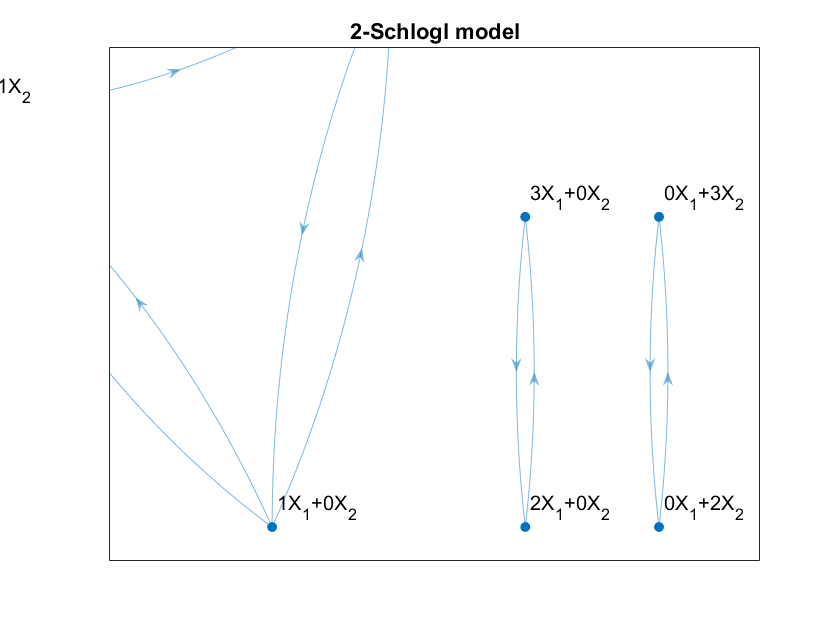

model_name = "Selkov"

Selkov_model
plotnam = "Selkov model"
Hypergraph_plotter

### Networks from Feinberg CRN software output formatted files

- Syntrophy network

- Cluster model networks

#### Syntrophy

clear all

model_name = "Selkov"

  
model_name = "SYN3_FINAL"

plotnam = "Selkov model"

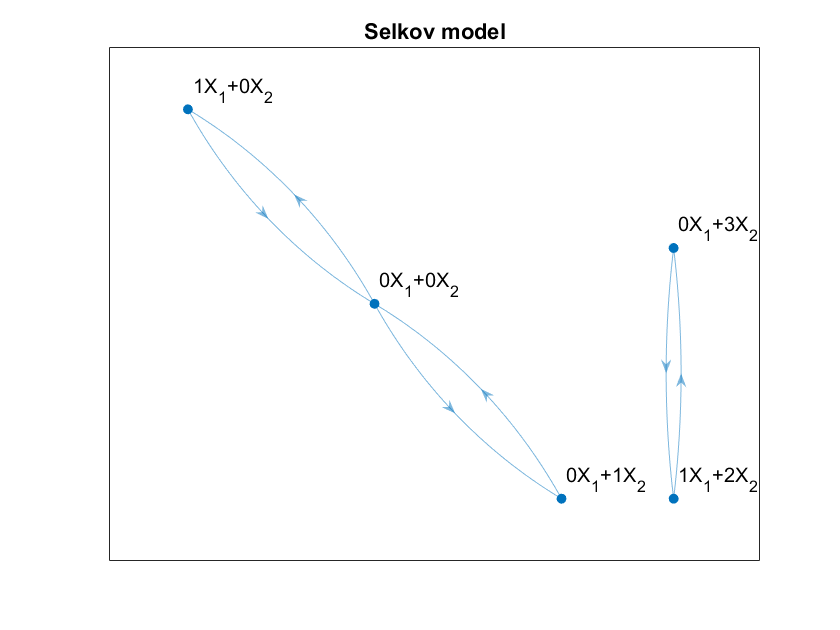

filnam = '..\Data\'+ model_name;

Extract_rxn_net_feinberg_1

#### Cluster w/Catalysis

clear all

$$Ham = \left(0.0023\,{\mathrm{e}}^{p_{1}-p_{2}}-0.0023\right)\,{q_{2}}^{3}+q_{1}\,\left(0.0023\,{\mathrm{e}}^{p_{2}-p_{1}}-0.0023\right)\,{q_{2}}^{2}+\left(1.3333\,{\mathrm{e}}^{-p_{2}}-1.3333\right)\,q_{2}+54.0408\,{\mathrm{e}}^{p_{1}}+1.9592\,{\mathrm{e}}^{p_{2}}+q_{1}\,\left(0.6667\,{\mathrm{e}}^{-p_{1}}-0.6667\right)-56$$

$$Eqns = \left(\begin{array}{c} \left(\frac{0.0023\,z_{1}}{z_{2}}-0.0023\right)\,{q_{2}}^{3}+q_{1}\,\left(\frac{0.0023\,z_{2}}{z_{1}}-0.0023\right)\,{q_{2}}^{2}+\left(\frac{1.3333}{z_{2}}-1.3333\right)\,q_{2}+54.0408\,z_{1}+1.9592\,z_{2}+q_{1}\,\left(\frac{0.6667}{z_{1}}-0.6667\right)-56=0\\ -\frac{z_{2}\,\left(\frac{1.3333\,q_{2}}{{z_{2}}^{2}}-\frac{0.0023\,q_{1}\,{q_{2}}^{2}}{z_{1}}+\frac{0.0023\,{q_{2}}^{3}\,z_{1}}{{z_{2}}^{2}}-1.9592\right)}{z_{1}\,\left(\frac{0.0023\,{q_{2}}^{3}}{z_{2}}-\frac{0.6667\,q_{1}}{{z_{1}}^{2}}-\frac{0.0023\,q_{1}\,{q_{2}}^{2}\,z_{2}}{{z_{1}}^{2}}+54.0408\right)}=\frac{{\mathrm{dq}}_{2}}{{\mathrm{dq}}_{1}} \end{array}\right)$$

model_name = "Cluster_3_catalyst"
filnam = '..\Data\'+ model_name;
plotnam = "3-D Cluster model with catalysis"
Extract_rxn_net_feinberg_1

#### Cluster w/catalyst+template

clear all
model_name = "Cluster_3_catalyst_w_temp"

ans = 10

ans = 5

filnam = '..\Data\'+ model_name;
plotnam = "3-D Cluster model with catalysis & templating"
Extract_rxn_net_feinberg_1

Notice, the X_i label is arbirary. Whereas, in the cluster index C_i, the index i is a cluster lattice index. The vector v_i = i is a conserved vector for a realistic cluster Hamiltonian denoting a closed system.

## Hamiltonian and derivatives

Save _Ham.mat in 'data' folder

Extract_Hamiltonian

filnam_sol = "..\Data\Selkov_bert_roots.txt"

pos_root_arr =    80.0000    2.0000
   48.0000   18.0000
   68.0000    8.0000


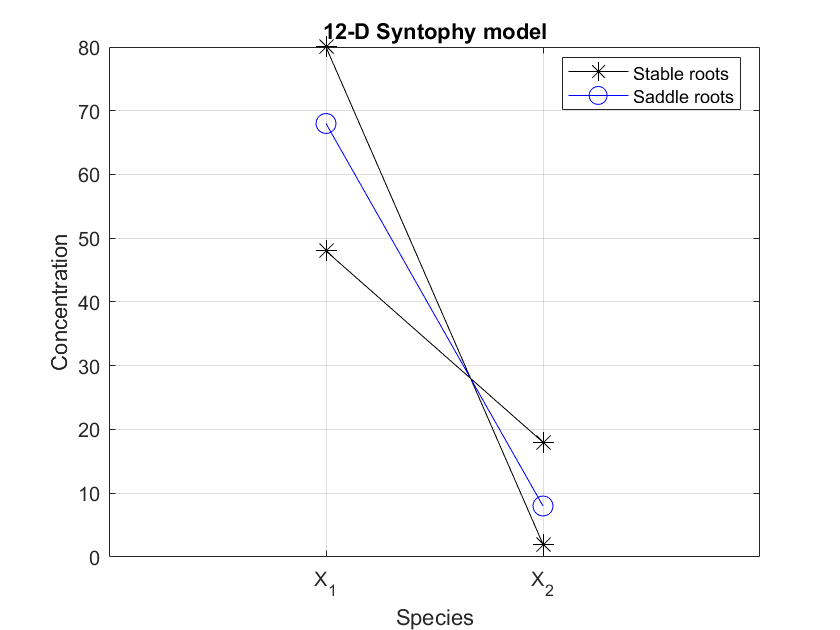

save('..\Data\'+model_name+'_Ham.mat')

load _Ham.mat from 'data' folder

$$pos\_root\_arr = \left(\begin{array}{ccc} 15.2195 & 2.1677 & 12.3127\\ 1.5159 & 0.2159 & 0.0435\\ 3.5437 & 0.5047 & 0.2474 \end{array}\right)$$

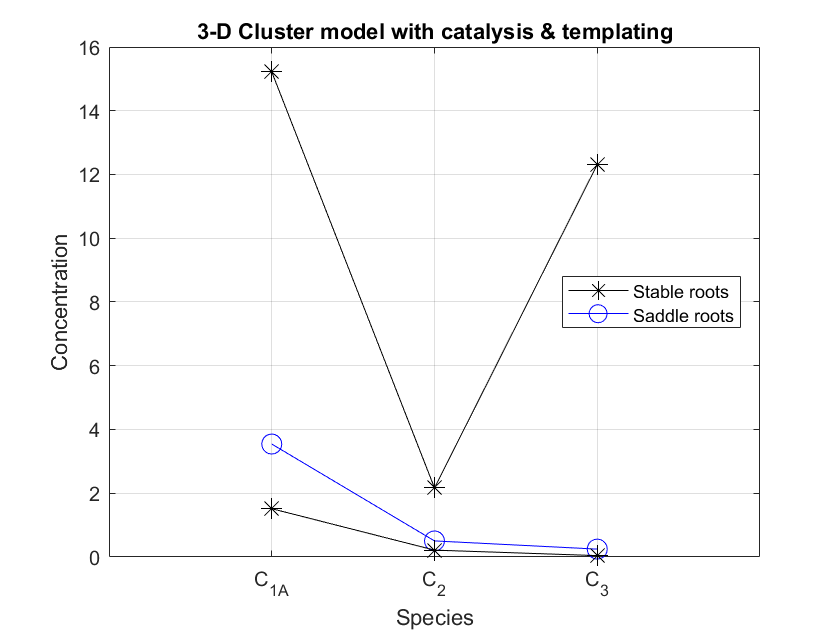

load('..\Data\'+model_name+'_Ham.mat')

## Get input for Bertini

Bertini is a polynomial root solver which takes input in a specific format and outputs all the roots of the system of polynomials.

$$pos\_root\_arr = \left(\begin{array}{cc} 79.9299 & 2.0152\\ 47.4517 & 18.2625\\ 68.5305 & 7.7177 \end{array}\right)$$

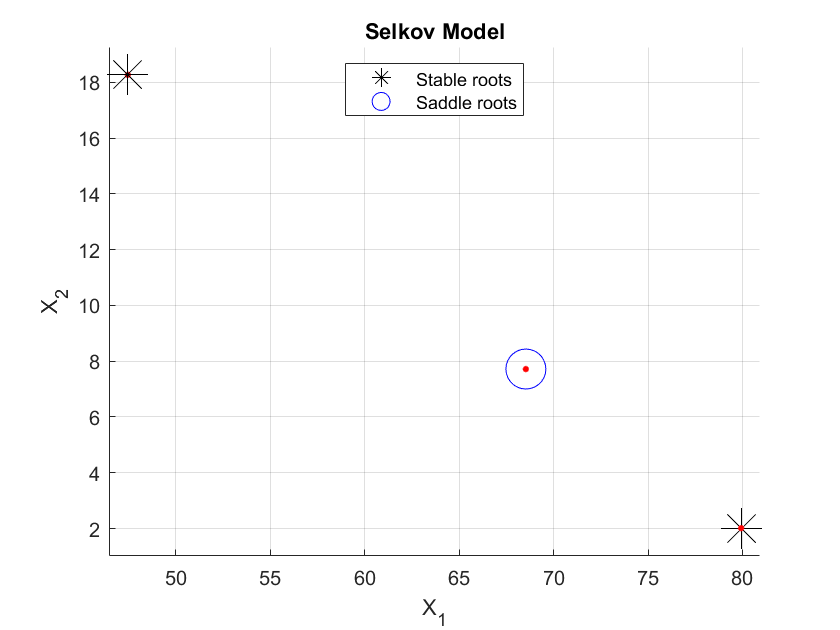

stab_idx =      1
     5
     6
     7


$$pos\_root\_arr = \left(\begin{array}{ccc} 11.1073 & 1.5820 & 2.3130\\ 1.5032 & 0.2141 & 0.0424\\ 4.0862 & 0.5820 & 0.3130 \end{array}\right)$$

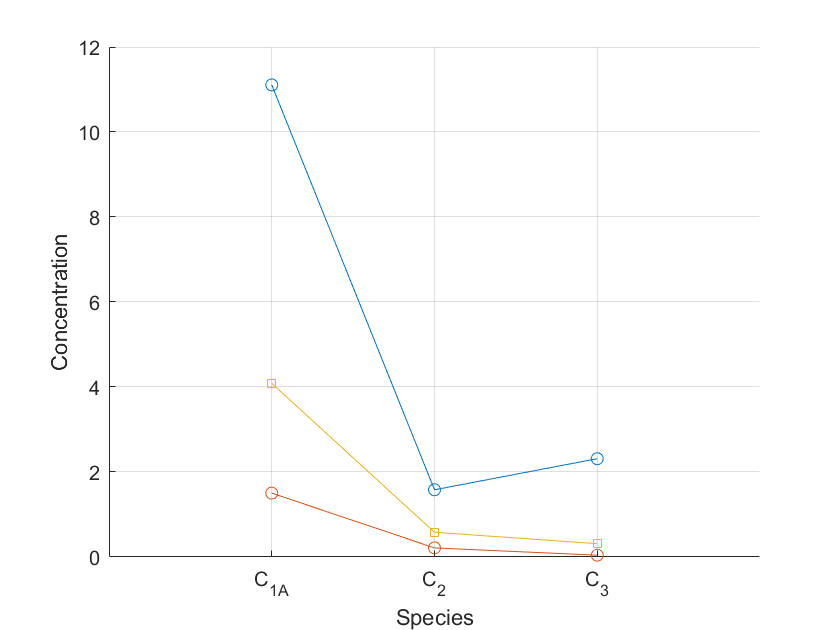

filnam = '..\Data\Bertini\'+model_name + "_bert.txt";
Bertini_file_input

Now open cygwin and use

>>cd  .../Data/Bertini

>>./Bertini filnam

Then rename real_finite_solutions file as filnam_roots.txt and paste in the Data folder.

## Get roots

#### Bertini

ans = "Computing time"

Elapsed time is 0.101341 seconds.


ans = "Simulation time"

ans = 47.4900

ans = "Computing time"

Elapsed time is 0.055294 seconds.


ans = "Simulation time"

ans = 52.2450

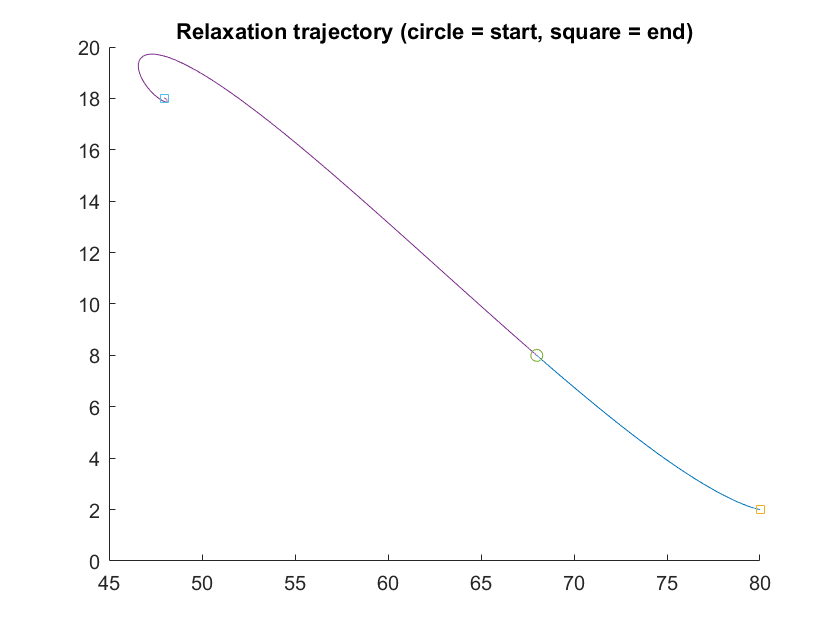

hc_net =      3     1     2


pos_root_arr =    80.0000    2.0000
   48.0000   18.0000
   68.0000    8.0000


filnam_sol = '..\Data\'+model_name+ "_bert_roots.txt"

Read_bert_root

Plots are saved in '4 Plot and publish' folder.

#### 3+ dim MATLAB roots

get_roots

#### 2 dim MATLAB roots

get_roots_2D

## Heteroclinic Network

Data saved in

'..\Data\' + model_name + '_hq qcnet.mat'

Heteroclinic_network

## Updates needed

- Textboxes indiciating root stability decomposition in the Bertini root output plots. How many roots are there of each morse index/morse index decomposition of roots. Change in morse index of dynamical system is one formulation of phase transitions for a Stochastic population process (SPP). The change of root decomposition is the object of study of Morse and CERF theory, and it would be good to find diagrammatic rules for predicting the topology of phase after transition.

- Need to write a shell script to do get bertini root file.